# Expansion valve modelling

## Introduction

This live script fits 4 different types of mass flow model to experimental data collected from an automotive reversible heat pump system operating in cooling (air-conditioning) mode. More details can be found in the ReadMe file included in the repository.

eevLoadAndAssign

## Define conditions for model fitting

All "steady" data - judged by EXV lift, upstream and downstream pressures:

% EXV steady:
    c_1 = mvngWndwSteady(time, lift_crrctd, 1, 120, 0.02)';
% Compressor on:
    comprSpeedSf = interp1(comprClutch.comprClutchDateTime, double(comprClutch.comprClutchValue),...
                           TD.Date_Time, 'previous'); % Scale factor for compressor speed
    omegaCompr = comprSpeedSf.*filterCompr(TD.omegaCompRpm);
    c_2 = omegaCompr > 50;
% Compressor steady:
    c_3 = mvngWndwSteady(time, omegaCompr, 1, 120, 100)';
% Steady upstream pressure:
    c_4 = mvngWndwSteady(time, Pup, 1, 60, 5)';
% Compile conditions:
c = c_1 & c_2 & c_3 & c_4;

## Model fitting (all steady data)

Use this section for randomising each time:

% c = find(c2); % Choose condition
% fitFrctn = 0.7; % 70 % of data used for fitting, 30% for validation.
% c_perm = randperm(numel(c))'; % A permutation of the condition vector (c)
% cf = c(c_perm(1:floor(numel(c)*fitFrctn))); % Data for model fitting
% cv = c(c_perm(ceil(numel(c)*fitFrctn):end)); % Data for model validation

Use this line for the same fitting and validation data each time (70 % was used for fitting and 30 % for validation):

load('FitValConditions.mat')

### Constant-coefficient models

There are two types of constant-coefficient model:

- Single-phase orifice mass flow form ($\dot{m} = CA \sqrt{ \rho_{up}\Delta P}$);

- Choked flow orifice mass flow form ($\dot{m} = CA \sqrt{\rho_{up}P_{up}}$);

% Single-phase orifice mass flow form:
C1_1 = cdIncomp1(mdot_crrctd(cf),lift_crrctd(cf)*Amax,Pup(cf),Pdown(cf),rhoup(cf));
mdot_model1_1 = mdotIncomp1(C1_1,lift_crrctd(cv)*Amax,Pup(cv),Pdown(cv),rhoup(cv));
nrmseM1_1 = NRMSE(mdot_model1_1, mdot_crrctd(cv));

% Choked flow orifice mass flow form:
Cd1_2 = cdIncomp2(mdot_crrctd(cf),lift_crrctd(cf)*Amax,Pup(cf),rhoup(cf));
mdot_model1_2 = mdotIncomp2(Cd1_2,lift_crrctd(cv)*Amax,Pup(cv),rhoup(cv));
nrmseM1_2 = NRMSE(mdot_model1_2, mdot_crrctd(cv));

% Display results:
disp(['C1.1 = ',num2str(C1_1)])

C1.1 = 0.36189


disp(['C1.2 = ',num2str(Cd1_2)])

C1.2 = 0.30263


disp(['NRMSE 1.1: ',num2str(nrmseM1_1)])

NRMSE 1.1: 35.5393


disp(['NRMSE 1.2: ',num2str(nrmseM1_2)])

NRMSE 1.2: 41.2754


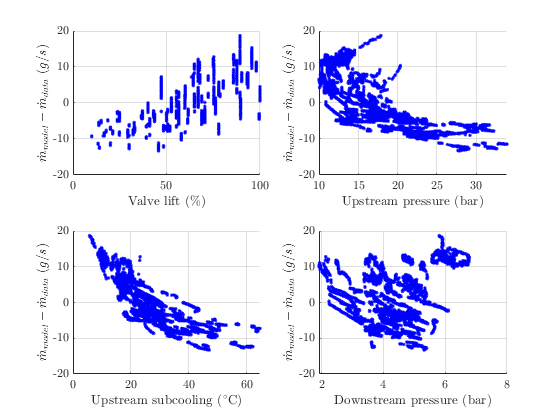


% Display residuals for non-choked form:
plotResiduals(mdot_model1_1, mdot_crrctd(cv), lift_crrctd(cv), Pup(cv), Tscup(cv), Pdown(cv))

### Polynomial-coefficient models

There are three groups of polynomial-coefficient models:

- Single-phase orifice mass flow form ($\dot{m} = CA \sqrt{ \rho_{up}\Delta P}$);

- Choked flow orifice mass flow form ($\dot{m} = CA \sqrt{\rho_{up}P_{up}}$);

- Combined form ($\dot{m}=CAY\sqrt{2\rho_{up}P_{up}X}$).

Each group then has the "simplified" and "generalised" polynomial forms:

- Simplified: $C_{D}= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)$

- Generalised: $C_{D}= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)+a_{4} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right) +a_{5} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)^{2}$

#### Single-phase orifice mass flow form:

% Simplified:
C2_1 = coeffsPolyCd1_1(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc);
C2_1 = round(C2_1, 4, 'significant');
mdot_model2_1 = mdotPolyCd1_1(C2_1,lift_crrctd(cv)*Amax,lift_crrctd(cv),Pup(cv),Pdown(cv),rhoup(cv),Tscup(cv),Tc);
nrmseM2_1 = NRMSE(mdot_model2_1, mdot_crrctd(cv));

% Generalised:
C2_2 = coeffsPolyCd1_2(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc);
C2_2 = round(C2_2, 4, 'significant');
mdot_model2_2 = mdotPolyCd1_2(C2_2,lift_crrctd(cv)*Amax,lift_crrctd(cv),Pup(cv),Pdown(cv),rhoup(cv),Tscup(cv),Tc);
nrmseM2_2 = NRMSE(mdot_model2_2, mdot_crrctd(cv));

#### Choked flow orifice mass flow form:

% Simplified:
C2_3 = coeffsPolyCd2_1(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),rhoup(cf),Tscup(cf),Tc);
C2_3 = round(C2_3, 4, 'significant');
mdot_model2_3 = mdotPolyCd2_1(C2_3,lift_crrctd(cv)*Amax,lift_crrctd(cv),Pup(cv),rhoup(cv),Tscup(cv),Tc);
nrmseM2_3 = NRMSE(mdot_model2_3, mdot_crrctd(cv));

% Generalised
C2_4 = coeffsPolyCd2_2(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),rhoup(cf),Tscup(cf),Tc);
C2_4 = round(C2_4, 4, 'significant');
mdot_model2_4 = mdotPolyCd2_2(C2_4,lift_crrctd(cv)*Amax,lift_crrctd(cv),Pup(cv),rhoup(cv),Tscup(cv),Tc);
nrmseM2_4 = NRMSE(mdot_model2_4, mdot_crrctd(cv));

#### Combined orifice mass flow form:

% Calculation of heat capacity ratio required: 
fprops = addCvGamma(fprops,'R1234YF');
gamma = interpn(fprops.liquid.unorm, fprops.p*10, fprops.liquid.gamma, unormup, ...
                    saturate(Pup, fprops.p_min*10, fprops.p_max*10)); % Heat capacity ratio
Fgamma = gamma/1.4;

% Simplified:
F1 = @(Xt)sum((cmbndPolyCd3_1(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc,Xt,gamma(cf)) - ...
    mdot_crrctd(cf)).^2) 

F1 = function_handle with value:
    @(Xt)sum((cmbndPolyCd3_1(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc,Xt,gamma(cf))-mdot_crrctd(cf)).^2)


Xt_1 = fminunc(F1,0.7);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


C2_5 = coeffsPolyCd3_1(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc,Xt_1,gamma(cf));
mdot_model2_5 = mdotPolyCd3_1(C2_5,lift_crrctd(cv)*Amax,lift_crrctd(cv),Pup(cv),Pdown(cv),rhoup(cv),Tscup(cv),Tc,Xt_1,gamma(cv));
nrmseM2_5 = NRMSE(mdot_model2_5, mdot_crrctd(cv));

% Generalised:
F2 = @(Xt)sum((cmbndPolyCd3_2(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc,Xt,gamma(cf)) - ...
    mdot_crrctd(cf)).^2)

F2 = function_handle with value:
    @(Xt)sum((cmbndPolyCd3_2(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc,Xt,gamma(cf))-mdot_crrctd(cf)).^2)


Xt_2 = fminunc(F2,0.7);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


C2_6 = coeffsPolyCd3_2(mdot_crrctd(cf),lift_crrctd(cf)*Amax,lift_crrctd(cf),Pup(cf),Pdown(cf),rhoup(cf),Tscup(cf),Tc,Xt_2,gamma(cf));
mdot_model2_6 = mdotPolyCd3_2(C2_6,lift_crrctd(cv)*Amax,lift_crrctd(cv),Pup(cv),Pdown(cv),rhoup(cv),Tscup(cv),Tc,Xt_2,gamma(cv));
nrmseM2_6 = NRMSE(mdot_model2_6, mdot_crrctd(cv));

#### Display results:

disp('C2.1 coefficients:')

C2.1 coefficients:


for Ix = 1:numel(C2_1)
    disp(['a',num2str(Ix-1),' = ',num2str(round(C2_1(Ix),4,'significant'))])
end

a0 = 0.7913
a1 = -1.488
a2 = 0.75
a3 = 4.716


disp('C2.2 coefficients:')

C2.2 coefficients:


for Ix = 1:numel(C2_2)
    disp(['a',num2str(Ix-1),' = ',num2str(round(C2_2(Ix),4,'significant'))])
end

a0 = 0.3383
a1 = -1.074
a2 = 0.7031
a3 = -0.5638
a4 = 9.054
a5 = -36.63


disp('C2.3 coefficients:')

C2.3 coefficients:


for Ix = 1:numel(C2_3)
    disp(['a',num2str(Ix-1),' = ',num2str(round(C2_3(Ix),4,'significant'))])
end

a0 = 0.709
a1 = -1.43
a2 = 0.7167
a3 = 4.932


disp('C2.4 coefficients:')

C2.4 coefficients:


for Ix = 1:numel(C2_4)
    disp(['a',num2str(Ix-1),' = ',num2str(round(C2_4(Ix),4,'significant'))])
end

a0 = 0.1315
a1 = -0.7419
a2 = 0.5456
a3 = -1.867
a4 = 10.09
a5 = -37.49


disp('C2.5 coefficients:')

C2.5 coefficients:


for Ix = 1:numel(C2_5)
    disp(['a',num2str(Ix-1),' = ',num2str(round(C2_5(Ix),4,'significant'))])
end

a0 = 1.097
a1 = -2.167
a2 = 1.091
a3 = 7.163


disp(['X_T 2.5 = ',num2str(Xt_1)])

X_T 2.5 = 0.90207


disp('C2.6 coefficients:')

C2.6 coefficients:


for Ix = 1:numel(C2_6)
    disp(['a',num2str(Ix-1),' = ',num2str(round(C2_6(Ix),4,'significant'))])
end

a0 = 0.3176
a1 = -1.199
a2 = 0.8229
a3 = -1.591
a4 = 12.44
a5 = -47.94


disp(['X_T 2.6 = ',num2str(Xt_2)])

X_T 2.6 = 1.2382



disp(['NRMSE 2.1: ',num2str(nrmseM2_1)])

NRMSE 2.1: 14.1755


disp(['NRMSE 2.2: ',num2str(nrmseM2_2)])

NRMSE 2.2: 12.3647


disp(['NRMSE 2.3: ',num2str(nrmseM2_3)])

NRMSE 2.3: 14.6297


disp(['NRMSE 2.4: ',num2str(nrmseM2_4)])

NRMSE 2.4: 12.7314


disp(['NRMSE 2.5: ',num2str(nrmseM2_5)])

NRMSE 2.5: 14.0726


disp(['NRMSE 2.6: ',num2str(nrmseM2_6)])

NRMSE 2.6: 12.3282


Plot residuals for generalised polynomial form coupled with the combined mass flow form:

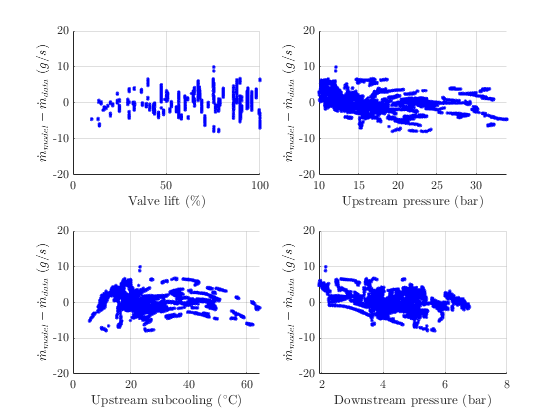

plotResiduals(mdot_model2_6, mdot_crrctd(cv), lift_crrctd(cv), Pup(cv), Tscup(cv), Pdown(cv))

### Power-law coefficient model

$\pi_{1}=a_{1} \cdot \pi_{2}^{a_{2}} \cdot \pi_{3}^{a_{3}} \cdot \pi_{4}^{a_{4}} \cdot \pi_{5}^{a_{5}} \cdot \pi_{6}^{a_{6}}$, $\pi_1 = \frac{m_{r}} {A \sqrt{2\rho_{i n}\left(p_{i n}-p_{o u t}\right)}}$ (also $C_d$), $\pi_2 = \frac{p_{in}-p_{sat}}{p_c}$, $\pi_3=\frac{t_{sub}}{t_c}$, $\pi_4=\frac{\nu_{v}}{\nu_{l}}$, $\pi_5=\frac{\sigma}{dp_{in}}$, $\pi_6=\frac{d_e}{d}$


$$\log{\pi_1}=\log{a_1}+a_2\log{\pi_2}+a_3\log{\pi_3}+a_4\log{\pi_4}+a_5\log{\pi_5}+a_6\log{\pi_6}$$


a_params = coeffsPowerLaw(mdot_crrctd(cf), lift_crrctd(cf)*Amax, Amax, Pup(cf), Pdown(cf), Pc, rhoup(cf), Tscup(cf), Tc, fprops);
a_params = round(a_params, 4, 'significant');
[mdot_model3, pis] = mdotPowerLaw(a_params, lift_crrctd(cv)*Amax, Amax, Pup(cv), Pdown(cv), Pc, rhoup(cv), Tscup(cv), Tc, fprops);
nrmseM3 = NRMSE(mdot_model3, mdot_crrctd(cv));

% Display results
% Show parameters:
for Ix = 1:numel(a_params)
    disp(['a',num2str(Ix),' = ',num2str(round(a_params(Ix),4,'significant'))])
end

a1 = 8.137e+21
a2 = 2.611
a3 = 0.4165
a4 = -4.794
a5 = 3.377
a6 = -0.7393


disp(['NRMSE 3: ',num2str(nrmseM3)])

NRMSE 3: 12.626


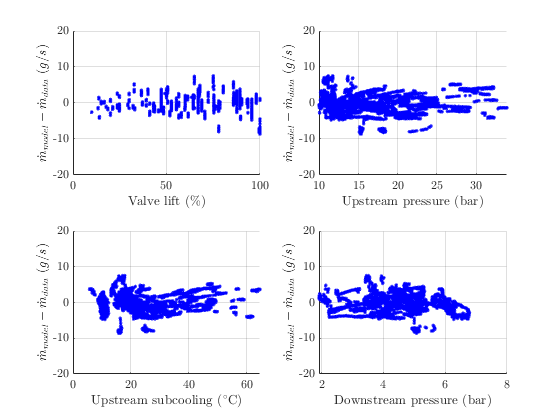


% Residuals:
plotResiduals(mdot_model3, mdot_crrctd(cv), lift_crrctd(cv), Pup(cv), Tscup(cv), Pdown(cv))

### Neuro-Fuzzy (LOLIMOT) model

LMN1 = lmnNFlol1(mdot_crrctd, lift_crrctd, Pup, Pdown, Tscup, cf, cv);

xInputDelay is empty, defaults are used: xInputDelay(1:p) = {0}
zInputDelay is empty, defaults are used: zInputDelay(1:p) = {0}
xOutputDelay is empty, defaults are used: xOutputDelay(1:p) = {[]}
zOutputDelay is empty, defaults are used: zOutputDelay(1:p) = {[]}



Initial net has 1 local linear model(s): J = 0.646013.


1. Iteration. Number of local linear models = 1. Checking for split of model 1 ...
   Testing split in dimension 1 with ratio 0.50: J = 0.403946.
   Testing split in dimension 2 with ratio 0.50: J = 0.455463.
   Testing split in dimension 3 with ratio 0.50: J = 0.596257.
   Testing split in dimension 4 with ratio 0.50: J = 0.405209.
-> Splitting in dimension 1 with ratio 0.50: J = 0.403946 and penalty = 0.404044.

2. Iteration. Number of local linear models = 2. Checking for split of model 3 ...
   Testing split in dimension 1 with ratio 0.50: J = 0.363095.
   Testing split in dimension 2 with ratio 0.50: J = 0.354114.
   Testing split in dimension 3 with ratio 0.50: J = 0.396362.
   Testing split in dimension 4 with ratio 0.50: J = 0.343089.
-> Splitting in dimension 4 with ratio 0.50: J = 0.343089 and penalty = 0.343178.

3. Iteration. Number of local linear models = 3. Checking for split of model 4 ...
   Testing split in dim

mdot_model4 = mdotNFlol1(LMN1, lift_crrctd(cv), Pup(cv), Pdown(cv), Tscup(cv));

nrmseM4 = NRMSE(mdot_model4, mdot_crrctd(cv));
disp(['NRMSE 4: ',num2str(nrmseM4)])

NRMSE 4: 6.8242


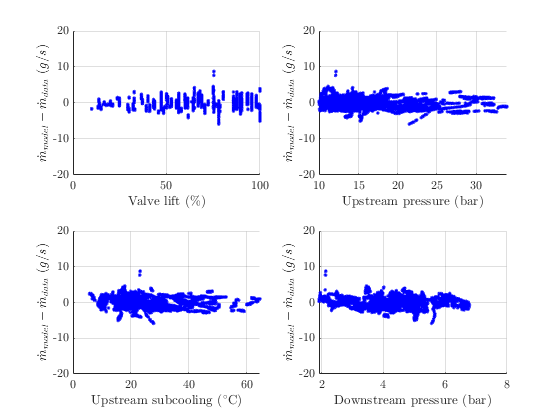


% Residuals:
plotResiduals(mdot_model4, mdot_crrctd(cv), lift_crrctd(cv), Pup(cv), Tscup(cv), Pdown(cv))

## Model Functions

1.1) Single-phase orifice mass flow equation:

Modified so constants are absorbed by C.


$$\dot{m} = CA \sqrt{ \rho_{up}\Delta P}$$


function Cd = cdIncomp1(mdot,A,Pup,Pdown,rhoup)
    Amat = A.*sqrt(saturate(Pup - Pdown,0,inf)*1e5.*rhoup);
    Bmat = mdot;
    Cd = Amat\Bmat;
end

function mdot_model = mdotIncomp1(Cd,A,Pup,Pdown,rhoup)
    mdot_model = Cd.*A.*sqrt(saturate(Pup - Pdown, 0, inf)*1e5.*rhoup);
end


1.2) Choked-flow form of single-phase orifice mass flow equation:


$$\dot{m} = CA \sqrt{\rho_{up}P_{up}}$$


function Cd = cdIncomp2(mdot,A,Pup,rhoup)
    Amat = A.*sqrt(Pup*1e5.*rhoup);
    Bmat = mdot;
    Cd = Amat\Bmat;
end

function mdot_model = mdotIncomp2(Cd,A,Pup,rhoup)
    mdot_model = Cd.*A.*sqrt(Pup*1e5.*rhoup);
end


2.1) Simplified polynomial coefficient (single-phase orifice mass flow form):

$C= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)$ with $\dot{m} = CA \sqrt{ \rho_{up}\Delta P}$

function Cs = coeffsPolyCd1_1(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc)
    % Linear regression:
    Asub = A.*sqrt(saturate(Pup - Pdown, 0, inf)*1e5.*rhoup);
    terms = [ones(size(Asub)), z, z.^2, z.*Tscup./Tc];
    Amat = terms.*Asub;
    Bmat = mdot;
    Cs = Amat\Bmat;
end

function mdot_model = mdotPolyCd1_1(Cs,A,z,Pup,Pdown,rhoup,Tscup,Tc)
    terms = [ones(size(Pup)), z, z.^2, z.*Tscup./Tc];
    C = (Cs'*terms')';
    mdot_model = C.*A.*sqrt(saturate(Pup - Pdown, 0, inf)*1e5.*rhoup);
end

2.2) Generalised polynomial coefficient (single-phase orifice mass flow form):

$C_{D}= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)+a_{4} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right) +a_{5} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)^{2}$with $\dot{m}=CA\sqrt{\rho_{up}P_{up}}$

function Cs = coeffsPolyCd1_2(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc)
    % Linear regression:
    Asub = A.*sqrt(saturate(Pup - Pdown, 0, inf)*1e5.*rhoup);
    terms = [ones(size(Asub)), z, z.^2, z.*Tscup./Tc, Tscup./Tc, (Tscup./Tc).^2];
    Amat = terms.*Asub;
    Bmat = mdot;
    Cs = Amat\Bmat;
end

function mdot_model = mdotPolyCd1_2(Cs,A,z,Pup,Pdown,rhoup,Tscup,Tc)
    terms = [ones(size(Pup)), z, z.^2, z.*Tscup./Tc, Tscup./Tc, (Tscup./Tc).^2];
    Cd = (Cs'*terms')';
    mdot_model = Cd.*A.*sqrt(saturate(Pup - Pdown, 0, inf)*1e5.*rhoup);
end

2.3) Simplified polynomial coefficient (choked flow orifice mass flow form):

$C= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)$ with $\dot{m}=CA\sqrt{\rho_{up}P_{up}}$

function Cs = coeffsPolyCd2_1(mdot,A,z,Pup,rhoup,Tscup,Tc)
    % Linear regression:
    Asub = A.*sqrt(Pup*1e5.*rhoup);
    terms = [ones(size(Asub)), z, z.^2, z.*Tscup./Tc];
    Amat = terms.*Asub;
    Bmat = mdot;
    Cs = Amat\Bmat;
end

function mdot_model = mdotPolyCd2_1(Cs,A,z,Pup,rhoup,Tscup,Tc)
    terms = [ones(size(Pup)), z, z.^2, z.*Tscup./Tc];
    Cd = (Cs'*terms')';
    mdot_model = Cd.*A.*sqrt(Pup*1e5.*rhoup);
end

2.4) Generalised polynomial coefficient (choked flow orifice mass flow form):

$C_{D}= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)+a_{4} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right) +a_{5} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)^{2}$where $\dot{m}=CA\sqrt{\rho_{up}P_{up}}$

function Cs = coeffsPolyCd2_2(mdot,A,z,Pup,rhoup,Tscup,Tc)
    % Linear regression:
    Asub = A.*sqrt(Pup*1e5.*rhoup);
    terms = [ones(size(Asub)), z, z.^2, z.*Tscup./Tc, Tscup./Tc, (Tscup./Tc).^2];
    Amat = terms.*Asub;
    Bmat = mdot;
    Cs = Amat\Bmat;
end

function mdot_model = mdotPolyCd2_2(Cs,A,z,Pup,rhoup,Tscup,Tc)
    terms = [ones(size(Pup)), z, z.^2, z.*Tscup./Tc, Tscup./Tc, (Tscup./Tc).^2];
    Cd = (Cs'*terms')';
    mdot_model = Cd.*A.*sqrt(Pup*1e5.*rhoup);
end

2.5) Simplified polynomial coefficient (combined mass flow form):

$C= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)$ where $\dot{m}=CAY\sqrt{2\rho_{up}P_{up}X}$ where $X=\frac{P_{up}-P_{down}}{P_{up}$, $Y=1-\frac{X}{3F_{\gamma}X_T$, $F_{\gamma}=\frac{\gamma}{1.4}$

function Cs = coeffsPolyCd3_1(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma)
    
    Fgamma = gamma/1.4;
    X = saturate((Pup-Pdown)./Pup, 0, Fgamma*Xt); % Pressure differential ratio
    Y = 1 - X./(3*Fgamma*Xt);
    
    Asub = A.*Y.*sqrt(rhoup.*Pup*1e5.*X);
    terms = [ones(size(Asub)), z, z.^2, z.*Tscup./Tc];
    Amat = terms.*Asub;
    Bmat = mdot;
    Cs = Amat\Bmat;
end

function mdot_model = mdotPolyCd3_1(Cs,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma)
    Fgamma = gamma/1.4;
    X = saturate((Pup-Pdown)./Pup, 0, Fgamma*Xt); % Pressure differential ratio
    Y = 1 - X./(3*Fgamma*Xt);    

    terms = [ones(size(Pup)), z, z.^2, z.*Tscup./Tc];
    Cd = (Cs'*terms')';
    mdot_model = Cd.*A.*Y.*sqrt(rhoup.*Pup*1e5.*X);
end

function mdot_model = cmbndPolyCd3_1(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma)
    Cs = coeffsPolyCd3_1(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma);
    mdot_model = mdotPolyCd3_1(Cs,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma);
end

2.6) Generalised polynomial coefficient (combined mass flow form):

$C_{D}= a_{0}+a_{1} z+a_{2} z^{2}+a_{3} z \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)+a_{4} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right) +a_{5} \left(\frac{T_{\text {sub }}}{T_{\mathrm{c}}}\right)^{2}$ where $\dot{m}=CAY\sqrt{2\rho_{up}P_{up}X}$ where $X=\frac{P_{up}-P_{down}}{P_{up}$, $Y=1-\frac{X}{3F_{\gamma}X_T$, $F_{\gamma}=\frac{\gamma}{1.4}$

function Cs = coeffsPolyCd3_2(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma)
    
    Fgamma = gamma/1.4;
    X = saturate((Pup-Pdown)./Pup, 0, Fgamma*Xt); % Pressure differential ratio
    Y = 1 - X./(3*Fgamma*Xt);
    
    Asub = A.*Y.*sqrt(rhoup.*Pup*1e5.*X);
    terms = [ones(size(Asub)), z, z.^2, z.*Tscup./Tc, Tscup./Tc, (Tscup./Tc).^2];
    Amat = terms.*Asub;
    Bmat = mdot;
    Cs = Amat\Bmat;
end

function mdot_model = mdotPolyCd3_2(Cs,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma)
    Fgamma = gamma/1.4;
    X = saturate((Pup-Pdown)./Pup, 0, Fgamma*Xt); % Pressure differential ratio
    Y = 1 - X./(3*Fgamma*Xt);    

    terms = [ones(size(Pup)), z, z.^2, z.*Tscup./Tc, Tscup./Tc, (Tscup./Tc).^2];
    Cd = (Cs'*terms')';
    mdot_model = Cd.*A.*Y.*sqrt(rhoup.*Pup*1e5.*X);
end

function mdot_model = cmbndPolyCd3_2(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma)
    Cs = coeffsPolyCd3_2(mdot,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma);
    mdot_model = mdotPolyCd3_2(Cs,A,z,Pup,Pdown,rhoup,Tscup,Tc,Xt,gamma);
end

3) Power-law coefficient:

$\pi_{1}=a_{1} \cdot \pi_{2}^{a_{2}} \cdot \pi_{3}^{a_{3}} \cdot \pi_{4}^{a_{4}} \cdot \pi_{5}^{a_{5}} \cdot \pi_{6}^{a_{6}}$, $\pi_1 = \frac{m_{r}} {A \sqrt{2\rho_{i n}\left(p_{i n}-p_{o u t}\right)}}$ (also $C_d$), $\pi_2 = \frac{p_{in}-p_{sat}}{p_c}$, $\pi_3=\frac{t_{sub}}{t_c}$, $\pi_4=\frac{\nu_{v}}{\nu_{l}}$, $\pi_5=\frac{\sigma}{dp_{in}}$, $\pi_6=\frac{d_e}{d}$

By taking logarithms, coefficients can be fitted in a linear manner:


$$\log{\pi_1}=\log{a_1}+a_2\log{\pi_2}+a_3\log{\pi_3}+a_4\log{\pi_4}+a_5\log{\pi_5}+a_6\log{\pi_6}$$


function a_opt = coeffsPowerLaw(mdot, A, Amax, Pup, Pdown, Pc, rhoup, Tscup, Tc, fprops)
    De = sqrt(4*A/pi);
    Dnom = sqrt(4*Amax/pi);

    % Assign Pi's:    
    % Viscosities (assumed at downstream pressure):
    nul = interp1(fprops.p*10, fprops.liquid.nu(end,:), saturate(Pdown, fprops.p_min*10, fprops.p_max*10))/1e6; % Saturated liquid kinematic viscosity (m^2/s)
    nuv = interp1(fprops.p*10, fprops.vapor.nu(1,:), saturate(Pdown, fprops.p_min*10, fprops.p_max*10))/1e6; % Saturated vapour kinematic viscosity (m^2/s)
    % Surface tension
    sigma = calcSigma(saturate(Pdown,0.315,33.822),fprops,'R1234YF');
    
    pi1 = saturate(mdot,0,inf)./(A.*sqrt(2*rhoup.*saturate(Pup - Pdown,0.01,inf)*1e5));
    pi2 = saturate(Pup - Pdown, 0.01, inf)/Pc;
    pi3 = saturate(Tscup/Tc, 0.01, inf);
    pi4 = nuv./nul;
    pi5 = sigma/Dnom./(Pup*1e5);
    pi6 = saturate(De/Dnom, 0.01, inf);
    
    Amat = [ones(size(pi1)), log(pi2), log(pi3), log(pi4), log(pi5), log(pi6)];
    Bmat = log(pi1);
    
    coeffs = Amat\Bmat;
    a_opt = [exp(coeffs(1)); coeffs(2:end)];
end

function [mdot_model, pis] = mdotPowerLaw(coeffs, A, Amax, Pup, Pdown, Pc, rhoup, Tscup, Tc, fprops)
    De = sqrt(4*A/pi);
    Dnom = sqrt(4*Amax/pi);

    % Assign Pi's:    
    % Viscosities (assumed at downstream pressure):
    nul = interp1(fprops.p*10, fprops.liquid.nu(end,:), saturate(Pdown, fprops.p_min*10, fprops.p_max*10))/1e6; % Saturated liquid kinematic viscosity (m^2/s)
    nuv = interp1(fprops.p*10, fprops.vapor.nu(1,:), saturate(Pdown, fprops.p_min*10, fprops.p_max*10))/1e6; % Saturated vapour kinematic viscosity (m^2/s)
    % Surface tension
    sigma = calcSigma(saturate(Pdown,0.315,33.822),fprops,'R1234YF');
    
    pi2 = saturate(Pup - Pdown, 0.01, inf)/Pc;
    pi3 = saturate(Tscup/Tc, 0.01, inf);
    pi4 = nuv./nul;
    pi5 = sigma/Dnom./(Pup*1e5);
    pi6 = saturate(De/Dnom, 0.01, inf);
    
    pis = struct('pi1',0,'pi2',pi2,'pi3',pi3,'pi4',pi4,'pi5',pi5,'pi6',pi6);    
    pi1prdctn = mdotPowerLaw_subfun(coeffs, pis);
    mdot_model = pi1prdctn.*(A.*sqrt(2*rhoup.*saturate(Pup - Pdown, 0, inf)*1e5));
end

function fun = mdotPowerLaw_subfun(x, pis)
    fun = x(1) .*pis.pi2.^(x(2)) .*pis.pi3.^(x(3)) .*pis.pi4.^(x(4)) .*pis.pi5.^(x(5)) .*pis.pi6.^(x(6));
end

4) Neuro-fuzzy (LOLIMOT):

function LMN = lmnNFlol1(mdot, A, Pup, Pdown, Tscup, cf, cv)
    LMN = lolimot; % initialize lolimot object
    
    LMN.estimationProcedure = 'LS'; % Least squares
    
    % assign the training data as input and output of the model
    LMN.input = [A(cf), Pup(cf)*1e5, Pdown(cf)*1e5, Tscup(cf)];
    LMN.output = mdot(cf);
    LMN.testInput = [A(cv), Pup(cv)*1e5, Pdown(cv)*1e5, Tscup(cv)];
    LMN.testOutput = mdot(cv);
    
    % Custom settings:
    LMN.maxNumberOfLM = 20;
    LMN.kStepPrediction = 0; % Static model
    
    % Train the local model network object
    LMN = LMN.train;
end

function mdot_model = mdotNFlol1(LMN, A, Pup, Pdown, Tscup)
    mdot_model = calculateModelOutput(LMN, [A, Pup*1e5, Pdown*1e5, Tscup], []);
end

## Plotting Functions

Residual plots:

function plotResiduals(mdot_model, mdot_data, lift, Pup, Tscup, Pdown)
    figure
    defaultLatex
    subplot(2,2,1)
    scatter(lift*100, (mdot_model - mdot_data)*1e3, 'b.'); 
    grid on; ylim([-20,20])
    xlabel('Valve lift (\%)'); ylabel('$\dot{m}_{model}-\dot{m}_{data}$ ($g/s$)'); 
    subplot(2,2,2)
    scatter(Pup, (mdot_model - mdot_data)*1e3, 'b.'); 
    grid on; ylim([-20,20])
    xlabel('Upstream pressure (bar)'); ylabel('$\dot{m}_{model}-\dot{m}_{data}$ ($g/s$)'); 
    subplot(2,2,3)
    scatter(Tscup, (mdot_model - mdot_data)*1e3, 'b.'); 
    grid on; ylim([-20,20])
    xlabel('Upstream subcooling ($^{\circ}$C)'); ylabel('$\dot{m}_{model}-\dot{m}_{data}$ ($g/s$)'); 
    subplot(2,2,4)
    scatter(Pdown, (mdot_model - mdot_data)*1e3, 'b.'); 
    grid on; ylim([-20,20])
    xlabel('Downstream pressure (bar)'); ylabel('$\dot{m}_{model}-\dot{m}_{data}$ ($g/s$)'); 
end